Here I want to find the maximum angular acceleration of the ball downwards in the worst case scenario. This is to set a limit in the system to make sure we work within a safe limitation.

Not considering folowing: air resistance and rolling resistance.

Assume: No sliding ogly pure roll and no friction do to rooling.

Angle $\pm {20}^{\circ }$, working in area of 40 deg.

Picture on the force acting:

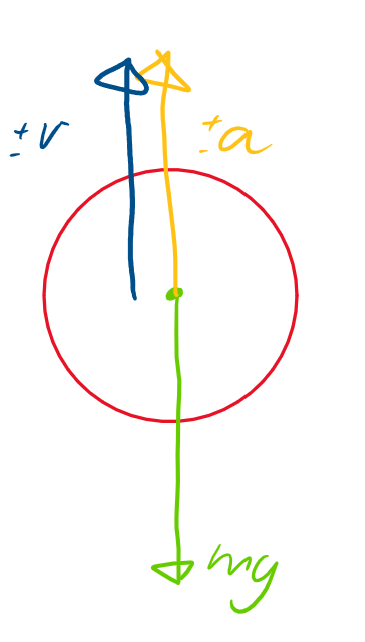

clc;close all; clear;
% defenition of variable:
m = 2.75 % grams

m = 2.7500

g = 9.81 % m/s^2

g = 9.8100

Length_of_beam = 0.71 % m

Length_of_beam = 0.7100

max_length_from_center = 0.3351 % m,The furthest distance from the center the ball can travel

max_length_from_center = 0.3351




% The worst cenario is when the ball is at the tip and the beam is
% accselerating down from horizontal.
a_max_tip = 9.81 % m/s^2

a_max_tip = 9.8100


% % finding max angular acceleration from top 20 deg going down:
g_20_down = cosd(20)*g

g_20_down = 9.2184

alpha_20_down =  g_20_down/max_length_from_center% rad/s^2

alpha_20_down = 27.5094



% finding max angular acceleration from horizontal going down:
alpha_0_down =  a_max_tip/max_length_from_center% rad/s^2

alpha_0_down = 29.2748


% alpha max based on worst scenario at the top:
alpha_max =  g_20_down/max_length_from_center% rad/s^2

alpha_max = 27.5094

The angular acceleration can not exid 29.2748$\frac{rad}{s^2}$ when the ball have a negativ acceleration horizontal going down. If so the ball will be in free fall and no contact.

The angular acceleration can not exid 27.5094$\frac{rad}{s^2}$ when the ball have a negativ acceleration at 20 deg at top going down. If so the ball will be in free fall and no contact.

Now we need to consider  that we dont want the ball to leave the beam at the tip.

First plot the vertical acceleration  $\pm {20}^{\circ }$:

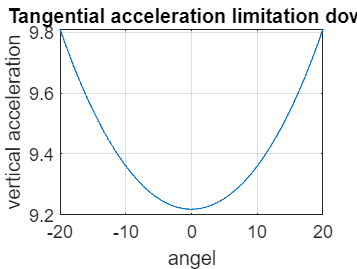

angle = linspace(-20,20,400);
rad = deg2rad(angle);
angle_rad = (cos(rad));
vertica_acceleration = (alpha_max*max_length_from_center)./angle_rad;
plot(angle,vertica_acceleration)
grid on
xlabel('angel')
ylabel('vertical acceleration')
title('Tangential acceleration limitation down')

This means that if the ball stops at 20 then the accel is 9.21838 $\frac{m}{s^2 }$ vertical 

Finds the length of the arc it accelerates

arc_deg =linspace(0,2*pi/9,400); % Going from -20 deg to 20 deg.
arc_lengt_1 = max_length_from_center*arc_deg; % m lengt from -20 to 20 deg

Finding the speed at the end vertically.

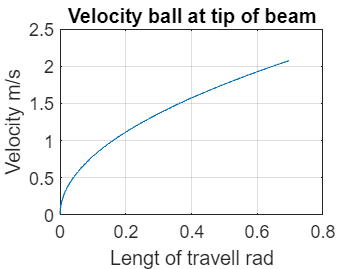

theta = arc_deg ; % -20 to 20 deg
t = sqrt((2*theta)/alpha_max); % s, time from -20 deg to 20 deg. 
omega_30 = alpha_max*t; % rot velocity from -20 to 20 deg over the arc lengt.
velocity_tang = omega_30*max_length_from_center; % m/s, tangential velosyty if alpha is constant and from min angel to max angel.

plot(theta,velocity_tang)
grid on
xlabel('Lengt of travell rad')
ylabel('Velocity m/s')
title('Velocity ball at tip of beam')
hold off

Finding how high the ball will go if the speed and acceleration is known. Stops at 20 deg at top after travel -20 to 20 deg..

%h = 1/100 %m
% energi_potensiell = m*g*h
% from -20 deg  stops at 20deg how high and fare will the ball go.
% This is only to show if the system have limits unvanted senarios can
% happen.
H_max =((velocity_tang).^2.*(sind(70)).^2)/(2*g) *10^3 % mm in the air

H_max =          0    0.4865    0.9730    1.4595    1.9461    2.4326    2.9191    3.4056    3.8921    4.3786    4.8652    5.3517    5.8382    6.3247    6.8112    7.2977    7.7842    8.2708    8.7573    9.2438    9.7303   10.2168   10.7033   11.1898   11.6764   12.1629   12.6494   13.1359   13.6224   14.1089   14.5955   15.0820   15.5685   16.0550   16.5415   17.0280   17.5145   18.0011   18.4876   18.9741   19.4606   19.9471   20.4336   20.9202   21.4067   21.8932   22.3797   22.8662   23.3527   23.8392


R_max =((velocity_tang).^2.*(sind(2*70)))/(g) *10^3 % mm in the air

R_max =          0    0.7083    1.4166    2.1249    2.8332    3.5415    4.2498    4.9582    5.6665    6.3748    7.0831    7.7914    8.4997    9.2080    9.9163   10.6246   11.3329   12.0412   12.7495   13.4579   14.1662   14.8745   15.5828   16.2911   16.9994   17.7077   18.4160   19.1243   19.8326   20.5409   21.2492   21.9576   22.6659   23.3742   24.0825   24.7908   25.4991   26.2074   26.9157   27.6240   28.3323   29.0406   29.7489   30.4572   31.1656   31.8739   32.5822   33.2905   33.9988   34.7071


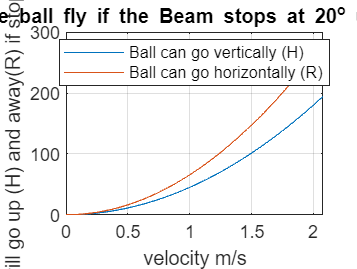

plot(velocity_tang,H_max)
hold on
plot(velocity_tang,R_max)
grid on
xlabel('velocity m/s')
ylabel('Ball will go up (H) and away(R) if stoped, mm')
legend('Ball can go vertically (H)','Ball can go horizontally (R)', 'Location','best')
title('How far can the ball fly if the Beam stops at 20^o up to max velocity')